# RTMDet Inference(五行code)

% Bulit on 2024.11.11 by Fred Liu
% MATLAB 2024b update
% Add-ons: Computer Vision Toolbox Model for RTMDet Object Detection

## **RTMDet**

**載入模型**

- `"tiny-network-coco"`

- `"small-network-coco"`

- `"medium-network-coco"` 

- `"large-network-coco"` 

detector = rtmdetObjectDetector("small-network-coco");

**載入影像**

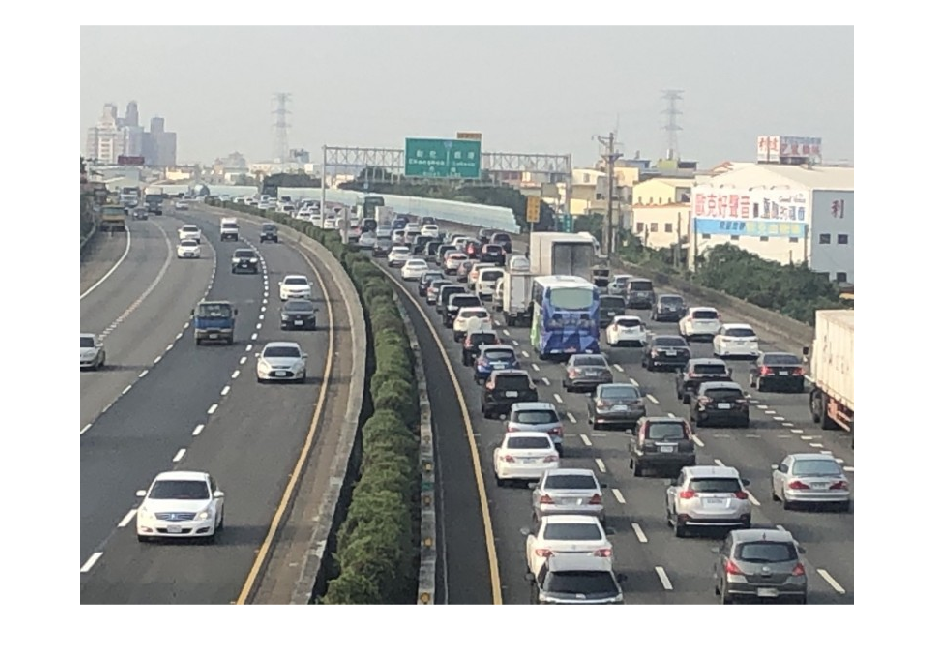

img = imread('Img/highway.jpg'); figure,imshow(img)

**進行辨識**

[bboxes,scores,labels] = detect(detector,img);

**畫標記框與顯示**

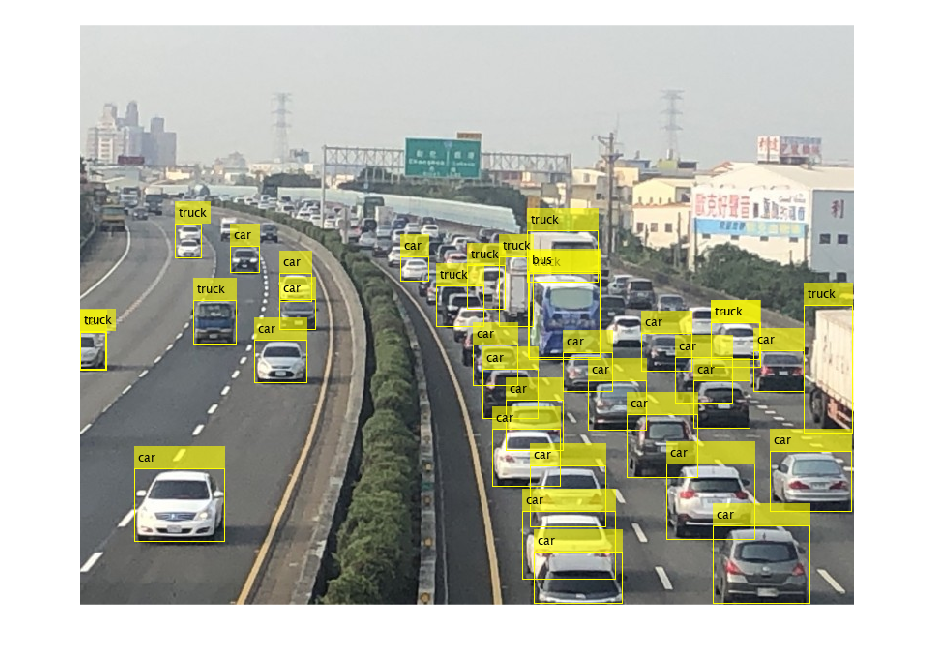

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure,imshow(detectedImg)

更換模型尺寸

detector2 = rtmdetObjectDetector("large-network-coco");

**進行辨識**

[bboxes2,scores2,labels2] = detect(detector2,img);

**畫標記框與顯示**

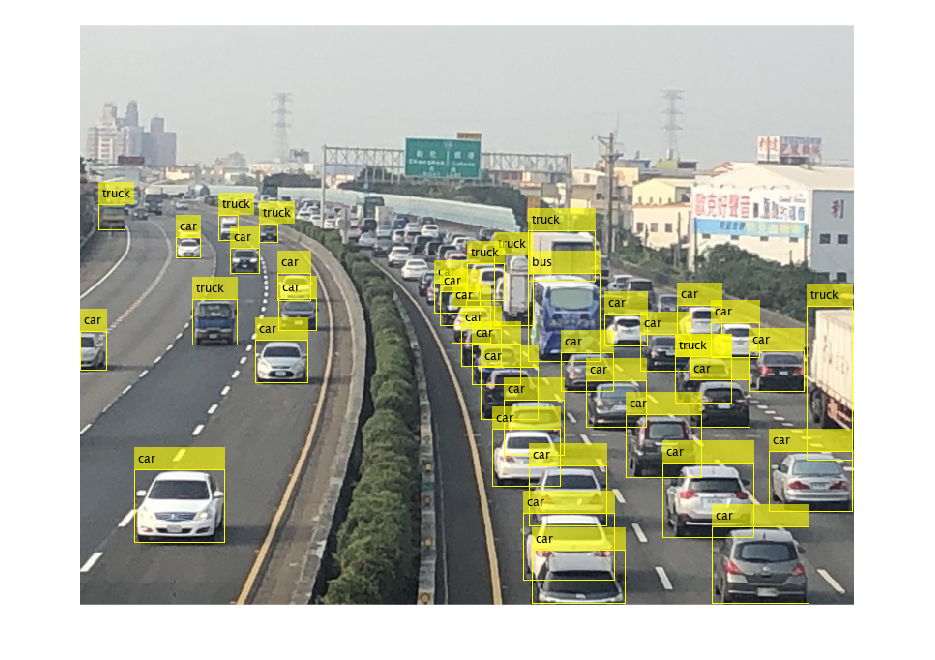

detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes2,labels2);
figure,imshow(detectedImg)